### ***2 - a***

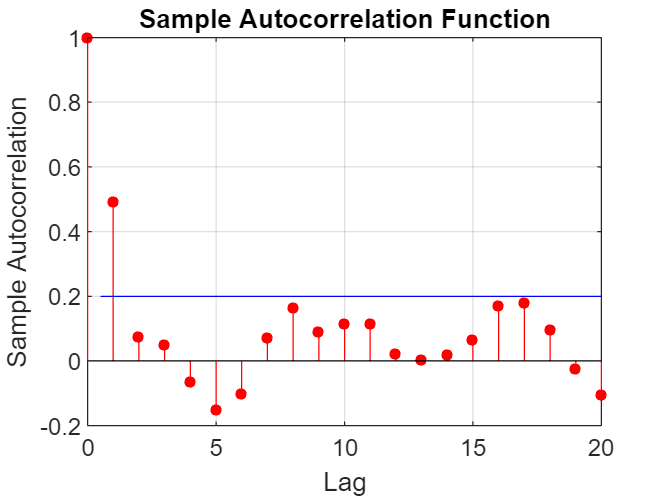

clc;
clear variables;
rng('default');
c1 = 0.6; %MA coefficient at lag = 1
R = 200; %No of Realisations
MA1 = arima('Constant',0,'MA',{0.6},'MAlags',[1],'Variance',1); %Creating MA(1) Process
%Simulating MA(1) process for 100 Observations and 200 Realisations
Y_ma1 = simulate(MA1,100,'NumPaths',R); 
%Plotting Autocorrelation Function(ACF) estimate values for lags for 1 Realisation
autocorr(Y_ma1(:,1)) 


a = autocorr(Y_ma1(:,1)); 
a(1) %Autocorrelation estimate value(ACF) for lag = 0

ans = 1

a(2) %Autocorrelation estimate value(ACF) for lag = 1

ans = 0.4924

### ***2 - b***

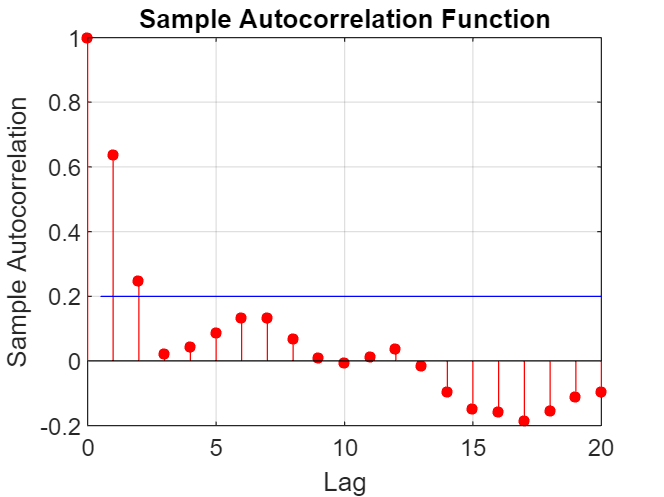

MA2 = arima('Constant',0,'MA',{0.6,0.4},'MAlags',[1,2],'Variance',1); %Creating MA(2) Process
%Simulating MA(2) process for 100 Observations and 200 Realisations
Y_ma2 = simulate(MA2,100,'NumPaths',R); 
%Plotting Autocorrelation Function(ACF) estimate values for lags for 1 Realisation

autocorr(Y_ma2(:,1))  

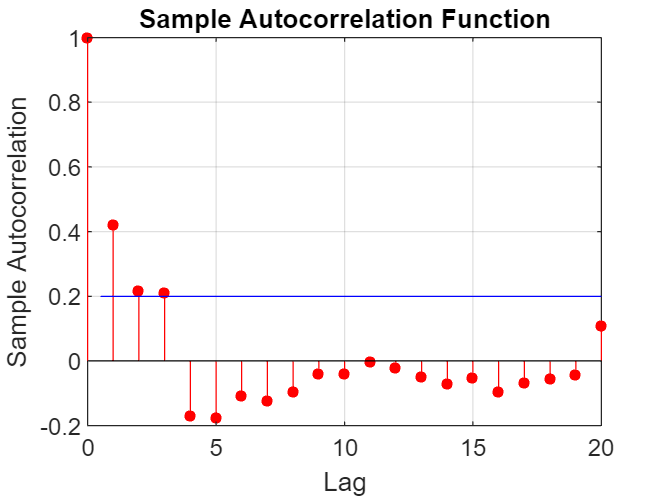

MA3 = arima('Constant',0,'MA',{0.6,0.4,0.7},'MAlags',[1,2,3],'Variance',1); %Creating MA(3) Process
%Simulating MA(3) process for 100 Observations and 200 Realisations
Y_ma3 = simulate(MA3,100,'NumPaths',R); 
%Plotting Autocorrelation Function(ACF) estimate values for lags for 1 Realisation
autocorr(Y_ma3(:,1)) 

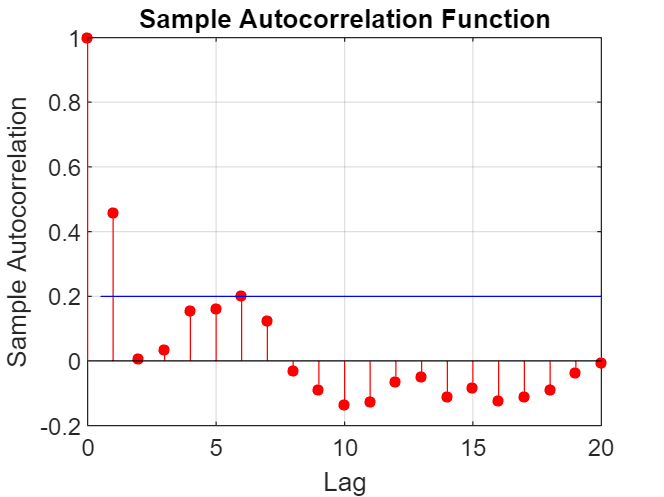

MA7 = arima('Constant',0,'MA',{0.6,0.02,0.01,0.2,0.05,0.1,0.2},'MAlags',[1,2,3,4,5,6,7],'Variance',1); %Creating MA(7) Process
%Simulating MA(7) process for 100 Observations and 200 Realisations
Y_ma7 = simulate(MA7,100,'NumPaths',R); 
%Plotting Autocorrelation Function(ACF) estimate values for lags for 1 Realisation
autocorr(Y_ma7(:,1)) 

### ***2 - c***

MA = arima('Constant',0,'MA',{0.6},'MAlags',[1],'Variance',1); %Creating MA(1) Process
%Simulating MA(1) process for 100 Observations and 200 Realisations
Y_ma = simulate(MA,100,'NumPaths',R);
b = zeros(2,R); %bias matrix
for i = 1:R
    %Autocorrelation Function(ACF) estimate values for lags for ith Realisation
    c = autocorr(Y_ma(:,i)); 
    %Autocorrelation Function(ACF) estimate values for lag = 1 for ith Realisation
    b(1,i) = (c(2)); 
    %Autocorrelation Function(ACF) estimate values for lag = 2 for ith Realisation
    b(2,i) = (c(3)); 
end    
mean(b,2) %Autocorrelation Function(ACF) estimate values for lag = 1 for ith Realisation

ans =     0.4238
   -0.0270


true = [c1/(1+(c1*c1));0] %Autocorrelation Function(ACF) actual values for lag = 1 for ith Realisation

true =     0.4412
         0


bias = (mean(b,2) - [c1/(1+(c1*c1));0]) %bias for estimates of ACF at lag = 1,2

bias =    -0.0174
   -0.0270


So, for 200 Realisations, the sample ACF's at lags = 1,2 are biased.

v = var(b,0,2) %variance for estimates of ACF at lag = 1,2

v =     0.0055
    0.0131


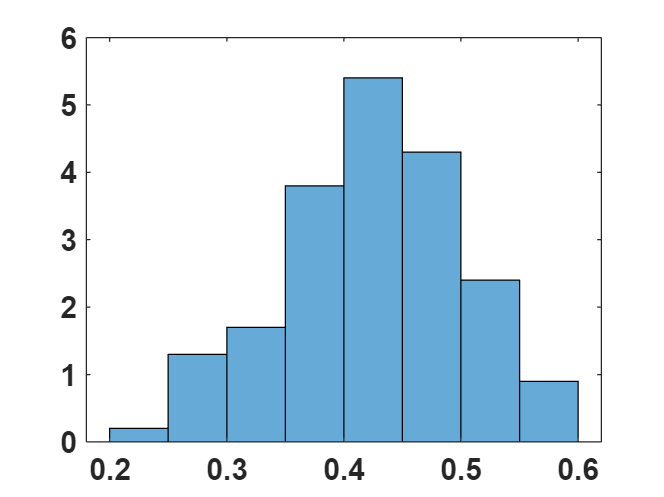

% Histogram for Distribution of estimates of ACF at lag = 1
figure;
hist_b1 = histogram(b(1,:), 'Normalization', 'pdf');
set(gcf,'Color',[1 1 1]);
set(gca,'fontsize',12,'fontweight','bold');

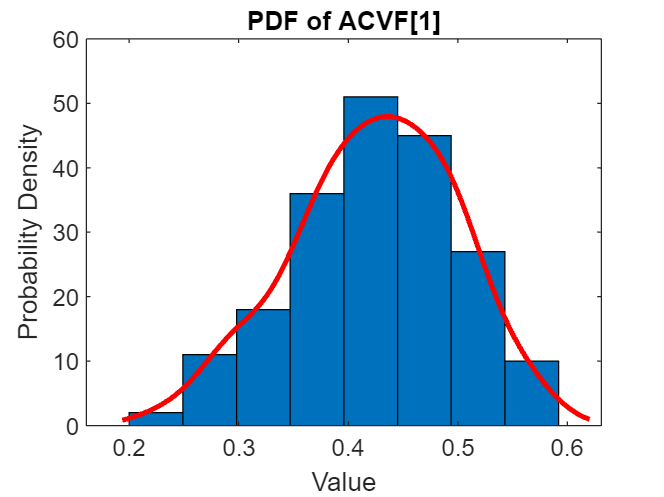

histfit(b(1,:),hist_b1.NumBins,"kernel")
title('PDF of ACVF[1]');
xlabel('Value');
ylabel('Probability Density');

The distribution of sample ACF at lag =1 for 200 realisations seems to Guassian.

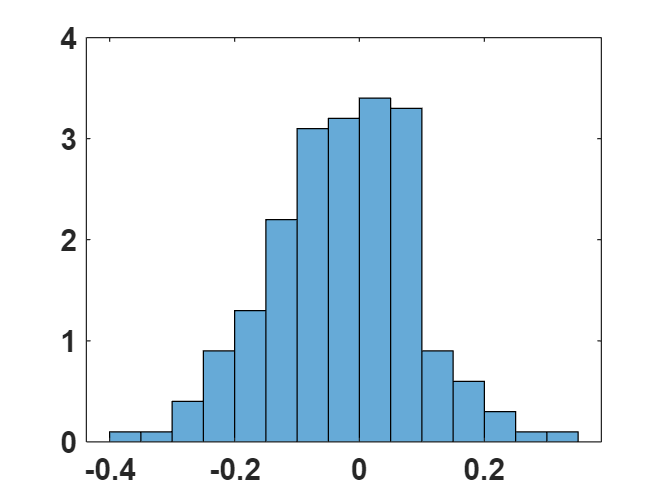

%Histogram for Distribution of estimates of ACF at lag = 1
figure;
hist_b2 = histogram(b(2,:), 'Normalization', 'pdf');
set(gcf,'Color',[1 1 1]);
set(gca,'fontsize',12,'fontweight','bold');

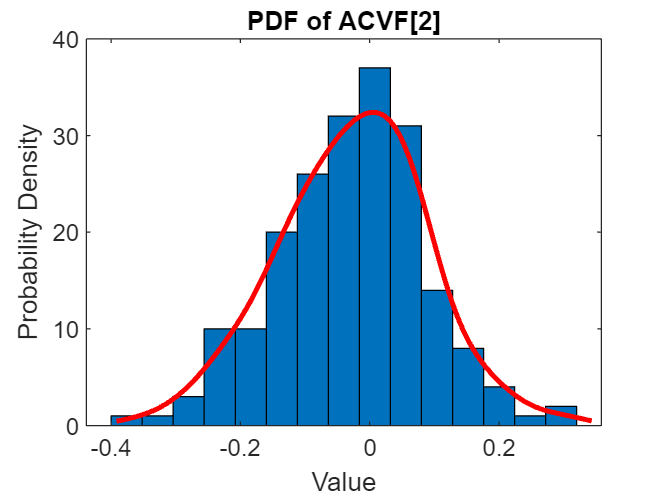

histfit(b(2,:),hist_b2.NumBins,"kernel")
title('PDF of ACVF[2]');
xlabel('Value');
ylabel('Probability Density');

The distribution of sample ACF at lag =2 for 200 realisations seems to Guassian.